# Compressed Sensing 

In solving the inverse problem:


$$y = Ax$$


Comnpressed sensing is the relaxed optimization problem:


$$\min \Vert x \Vert_1$$


subject to:                                  


$$\Vert Ax-y \Vert_2 = 0$$


This code uses the original package ( L1-Magic ) from Justin Romberg, Caltech. You can download a version of this package here ([ l1-magic ](https://github.com/scgt/l1magic)).

## Linear Regression

See l1eq_example.m file in the downloaded package.

clearvars; close all; clc;

addpath("l1magic/")%download the folder and add its path here
addpath("l1magic/Optimization/") 
addpath("l1magic/Measurements/")

% signal length
N = 512;
% number of spikes in the signal (In other words, number of non-zero
% parameters)
T = 10;

% number of observations to make
K = 120;

% random +/- 1 signal
x = zeros(N,1);
q = randperm(N);
x(q(1:T)) = sign(randn(T,1));


% measurement matrix
A = randn(K,N);
A = orth(A')'; %Creating the orthogonl measurements matrix

	
% observations
y = A*x;

Now, you have underdetermined system, where $A$ has more columns than rows.

% initial guess = least squares
x0 = pinv(A)*y; %Try the same code in the original package, what is the difference?
                %Also, try the least squares using the QR factorization
                %which is given by:  A\y



% solve the optimization problem 
tic
xp = l1eq_pd(x0, A, [], y, 1e-3);
toc

Elapsed time is 0.020839 seconds.


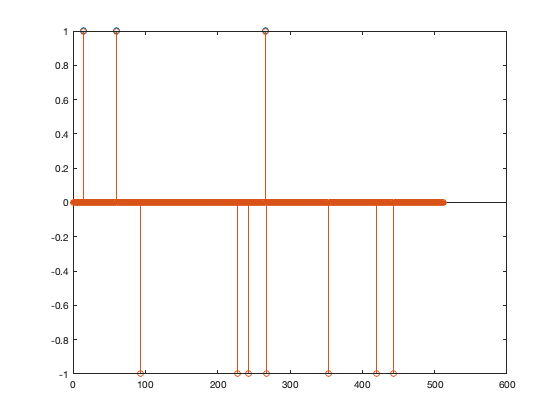


%plot the solution
stem(x)
hold on
stem(xp) %try to plot the least squares solution and see the difference
hold off

Try to solve the above problem using the iterative hard thresholding.

%Display
% TrueSolution - LeastSquaresSolution - CompressedSensingSolution

disp([x, x0, xp])

         0   -0.0221   -0.0000
         0   -0.0302   -0.0000
         0    0.0715    0.0000
         0    0.0289    0.0000
         0    0.0406    0.0000
         0    0.0757    0.0000
         0    0.0357    0.0000
         0   -0.0239   -0.0000
         0    0.0605    0.0000
         0    0.0081    0.0000
         0   -0.0090   -0.0000
         0   -0.0645   -0.0000
         0   -0.0323   -0.0000
    1.0000    0.1107    1.0000
         0    0.0191    0.0000
         0    0.0148    0.0000
         0    0.0092    0.0000
         0   -0.0493   -0.0000
         0   -0.0132   -0.0000
         0    0.0555    0.0000
         0   -0.0246   -0.0000
         0    0.0169    0.0000
         0    0.0114    0.0000
         0   -0.0137    0.0000
         0    0.0444    0.0000
         0   -0.0015   -0.0000
         0    0.0887    0.0000
         0   -0.1030   -0.0000
         0   -0.0263   -0.0000
         0    0.0633    0.0000
         0   -0.0488   -0.0000
         0    0.0467    0.0000
        

## Sparse Images Recoverey

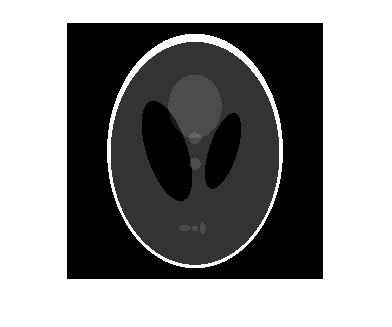

%Read Phantom image
n = 256;
N = n*n;
X = phantom(n);

imshow(X)

x = X(:);

% number of radial lines in the Fourier domain
L = 22;

% Fourier samples we are given
[M,Mh,mh,mhi] = LineMask(L,n);

Note: the idea is that we don't need to read all the image, just few measurements obtained using a mask will be enough to recover the image.

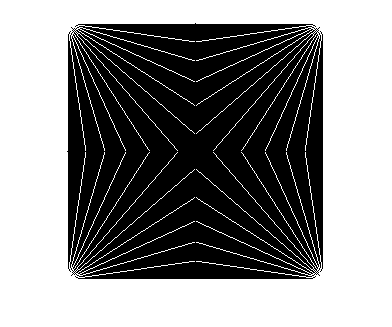

OMEGA = mhi; %Index of the sampled data.


A = @(z) A_fhp(z, OMEGA);
At = @(z) At_fhp(z, OMEGA, n);

imshow(M) %Show the mask 

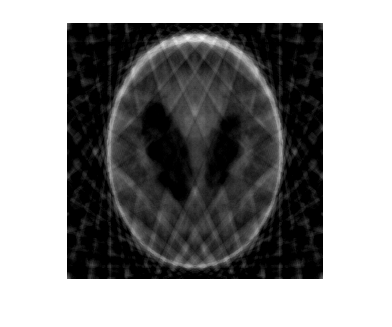




y = A(x);


% min l2 reconstruction (backprojection)
xbp = At(y);
Xbp = reshape(xbp,n,n);

imshow(reshape(Xbp,n,n))


xp = tveq_logbarrier(xbp, A, At, y, 1e-1, 2, 1e-8, 600);

Number of log barrier iterations = 15

Newton iter = 1, Functional = 22089.091, Newton decrement =  571.045, Stepsize = 3.236e+00
                  SYMMLQ Res = 2.318e-08, SYMMLQ Iter = 600
Newton iter = 2, Functional = 21862.617, Newton decrement =  192.321, Stepsize = 2.941e+00
                  SYMMLQ Res = 9.901e-09, SYMMLQ Iter = 530
Newton iter = 3, Functional = 21836.408, Newton decrement =   24.328, Stepsize = 1.463e+00
                  SYMMLQ Res = 9.271e-09, SYMMLQ Iter = 492
Newton iter = 4, Functional = 21835.895, Newton decrement =    0.505, Stepsize = 2.392e-01
                  SYMMLQ Res = 9.984e-09, SYMMLQ Iter = 443
Newton iter = 5, Functional = 21835.895, Newton decrement =    0.001, Stepsize = 8.932e-03
                  SYMMLQ Res = 9.658e-09, SYMMLQ Iter = 360

Log barrier iter = 1, TV = 2281.674, functional = 6645.879, tau = 2.371e+01, total newton iter = 5

Newton iter = 1, Functional = 13534.687, Newton decrement = 1291.509, Stepsize = 7.551e+00
              

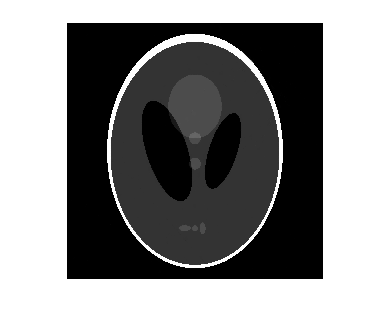

Xtv = reshape(xp, n, n);

imshow(reshape(Xtv,n,n))